# TBRe GPS Data activity

## 1. Load the data

What is in the file? How many variables, what shape, what type? Time-indexed GPS latitude, longitude and altitude, logged at 10 Hz.

load("Onboarding_GPS.mat")
whos GPS*

  Name         Size              Bytes  Class     Attributes

  GPSalt       1x9840            78720  double              
  GPSlat       1x9840            78720  double              
  GPSlon       1x9840            78720  double              
  GPStime      1x9840            78720  double              



## 2. What does the data look like?

The first few samples: time, latitude, longitude, altitude. Latitude and longitude are stored to 15 decimal places - set format long:

format long g
firstSamples = [GPStime(1:5); GPSlat(1:5); GPSlon(1:5); GPSalt(1:5)]'

firstSamples = 

    5.945    52.0787106223187    -1.01186729822032    202.159707850777
    6.045    52.0787193369835     -1.0118524655425    201.510229807507
    6.145    52.0787208749686     -1.0118516046504     201.49555909917
    6.245    52.0787162373074    -1.01186364314452    201.838943357079
    6.345    52.0787135838205    -1.01186960157359    200.347848243757


format short

## 3. We have coordinate data - where are we in the world?

Find by pasting the first position into Google Maps (satellite view):

mapsLink = "https://www.google.com/maps?q=" + num2str(GPSlat(1), 10) + "," + num2str(GPSlon(1), 10) + "&t=k"

mapsLink = "https://www.google.com/maps?q=52.07871062,-1.011867298&t=k"

web(mapsLink) 

## 4. Plot the coordinate data

Plot latitude against longitude.

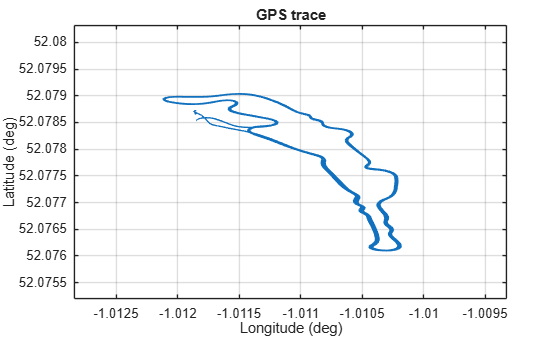

plot(GPSlon, GPSlat)
grid on
xlabel("Longitude (deg)")
ylabel("Latitude (deg)")
title("GPS trace")

## So, what is this data?

### We are at Copse corner in Silverstone - any guesses what our data shows?

### This is the FSUK endurance track map:

## 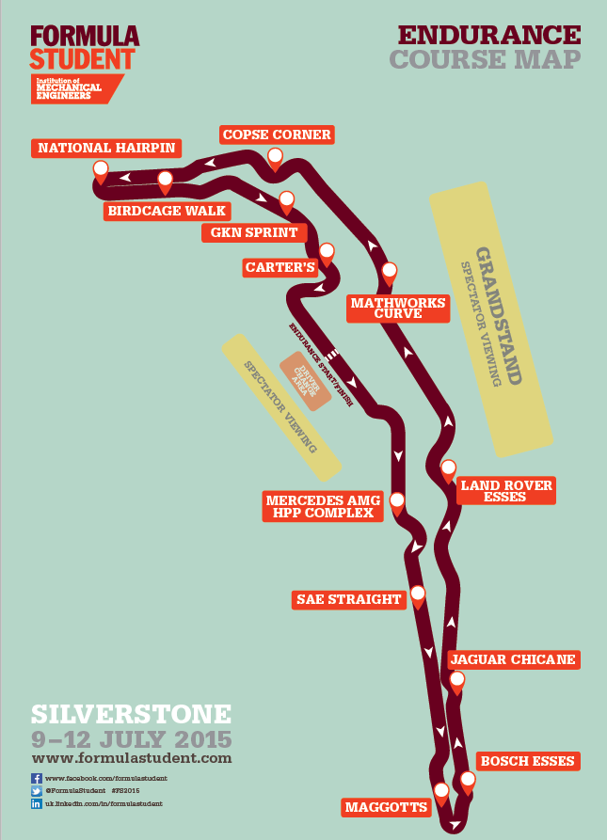

### The data is a full endurance stint from FSUK25

### **The first task, which we will go through together, is:**

## **What is the fastest laptime in this stint?**

## **What do we need to do with the data to find an answer?**

## **We need to split the data into laps - but what makes a lap?**

## A lap begins by crossing a line, and ends once the same line is crossed again.

## We need a coordinate-defined start / finish line so we can split the data.

## Where do we define it? Refer to the lat/lon plot and the track map image.

## 5. Defining a start/finish line

I picked these two points:

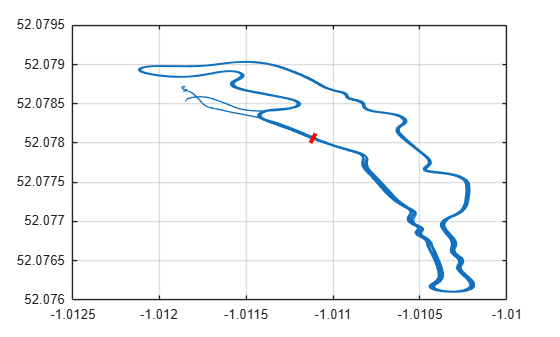

lineStart = [-1.0111, 52.07812];    % [lon lat]
lineEnd   = [-1.01113, 52.07800];   % [lon lat]




% Plot the GPS trace again, with a Start / Finish Line



plot(GPSlon, GPSlat)
hold on
plot([lineStart(1) lineEnd(1)], [lineStart(2) lineEnd(2)], "r", LineWidth=3)
hold off
grid on

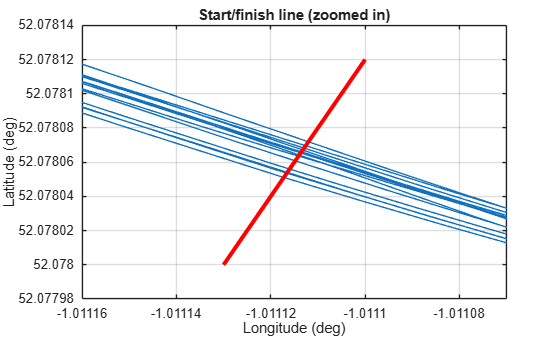

xlim([-1.01116 -1.01107])
ylim([52.07798 52.07814])

xlabel("Longitude (deg)")
ylabel("Latitude (deg)")
title("Start/finish line (zoomed in)")

## Now we have our S/F line, how can we use it to split laps?

## 6. Finding which side of the line is the car on: cross product of S/F direction & car position.

### The cross product of the line's direction with the car's position (relative to the start of the line) is positive on one side of the line and negative on the other. The car crosses the line wherever this changes sign from one sample to the next.

lineDir = lineEnd - lineStart;
side = lineDir(1) * (GPSlat - lineStart(2)) - lineDir(2) * (GPSlon - lineStart(1));
k = find(side(1:end-1) .* side(2:end) < 0);   % the car crosses between samples k and k+1
numSignChanges = numel(k)

numSignChanges = 28

## Does 28 sign changes = 28 laps?

## The cross product uses lineDir, which is infinitely long. Therefore the car crosses the line on the opposite side of the track, too.

## 7. Keeping only S/F line crosses

The car is heading the opposite direction on the opposite side of the track, so we keep only the crossings in the S/F direction of travel: from the negative side of the line to the positive side. IF YOU DEFINED YOUR S/F LINE THE OPPOSITE WAY ROUND OR USED THE OPPOSITE DIRECTION IN THE CROSS PRODUCT, USE k = k(side(k) **> 0**); 

k = k(side(k) < 0);   % negative before the line, positive after
numCrossings = numel(k)

numCrossings = 14

## We now have the index of every line crossing so can find GPStime at each index

## 8. Calculating Laptimes

Each lap starts at the first sample after the car crosses the line and ends at the first sample after it crosses again. The data before the first crossing (the out-lap) and after the last crossing (the in-lap) are not complete laps, **so they are not timed.**

crossTime = GPStime(k + 1);
lapTime = round(diff(crossTime), 1)';    % rounded to the 0.1 s time step
lap = (1:numel(lapTime))';
lapTimes = table(lap, lapTime)

lapTimes = 13×2 table
     1    67.5000
     2    66.9000
     3    64.9000
     4    63.5000
     5    65.9000
     6    66.3000
     7    65.6000
     8    64.7000
     9    64.2000
    10         67
    11    62.7000
    12    62.4000
    13    63.4000


[fastest, fastestLap] = min(lapTime);
disp("Fastest lap " + fastestLap + " in " + fastest + " s")

Fastest lap at 10 Hz: lap 12 in 62.4 s


## Are we restricted to 10hz laptimes?

## How can we do better?

## 9. Line crossing interpolation

We know how far the car is from the line before and after it crosses (`side`), so we can interpolate the moment it was exactly on the line.

frac = side(k) ./ (side(k) - side(k + 1));            % 0 = at sample k, 1 = at sample k+1
crossTimeInterp = GPStime(k) + frac .* (GPStime(k + 1) - GPStime(k));
lapTimeInterp = diff(crossTimeInterp)';
difference = round(lapTimeInterp - lapTime, 3);
comparison = table(lap, lapTime, lapTimeInterp, difference)

comparison = 13×4 table
     1    67.5000    67.4642    -0.0360
     2    66.9000    66.8817    -0.0180
     3    64.9000    64.8814    -0.0190
     4    63.5000    63.5748     0.0750
     5    65.9000    65.8288    -0.0710
     6    66.3000    66.3215     0.0220
     7    65.6000    65.6345     0.0340
     8    64.7000    64.6214    -0.0790
     9    64.2000    64.2774     0.0770
    10         67    66.9416    -0.0580
    11    62.7000    62.6816    -0.0180
    12    62.4000    62.4073     0.0070
    13    63.4000    63.4119     0.0120


[fastestInterp, fastestLapInterp] = min(lapTimeInterp);
disp("Fastest lap interpolated: lap " + fastestLapInterp + " in " + round(fastestInterp, 3) + " s")

Fastest lap interpolated: lap 12 in 62.407 s


## Extension tasks: What else can you do with this GPS data?

## We have position + time... therefore you can calculate distance (sRun), velocity (vCar) and acceleration (e.g gLat w.r.t car heading) vectors at each point

## You cannot directly find velocity or accel with coordinates: You need to convert the coordinates into meters.

## Why do you think my example has excluded GPSalt and all vertical vectors?

## I will share a simple script + more .mat files containing Throttle, Brake and Power. 

## Your extension task: Plot velocity, gLat, gLong, throttle, brake and power for each lap overlaid on each other. Ideally, plot against the distance domain (sLap) for corner comparison across laps.

## Further extension: Build an interactive data display and analyse where the fastest lap gains/loses time against the 2nd fastest

## Ideas for further detail: energy usage per lap, further lines for track sectors/segments (different crossing detection may be necessary for this), Satellite track map + racing line comparisons, etc.

## My example: Personal GPS lap explorer